%definicion de vectores de las variables 
x=[100,110,120,130,140,150,160,170,180,190];
y=[45,51,54,61,66,70,74,78,85,89];
%mediadas de tendencia central
xorden=sort(x)

xorden =    100   110   120   130   140   150   160   170   180   190


yorden=sort(y)

yorden =     45    51    54    61    66    70    74    78    85    89


xmedia=mean(x)

xmedia = 145

ymedia=mean(y)

ymedia = 67.3000

xmediana=median(xorden);
ymediana=median(yorden);
xmoda=mode(x)

xmoda = 100

ymoda=mode(y)

ymoda = 45

%medidas de dispersion
xvarianza=var(x)

xvarianza = 916.6667

yvarianza=var(y)

yvarianza = 214.6778

xdesviacion=std(x)

xdesviacion = 30.2765

ydesviacion=std(y)

ydesviacion = 14.6519

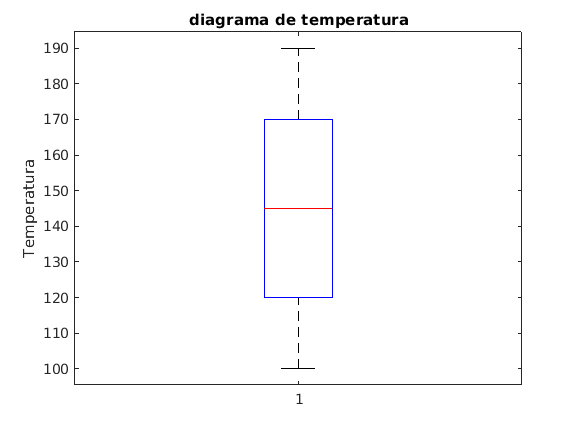

%driagramas de cajas y bigotes 
boxplot(x) 
ylabel('Temperatura') 
title('diagrama de temperatura')

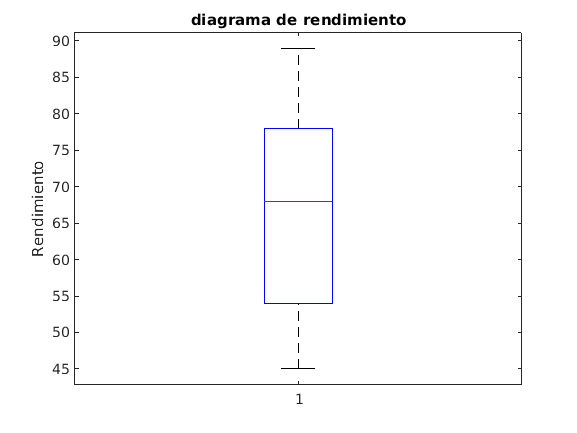

boxplot(y);
ylabel('Rendimiento') 
title('diagrama de rendimiento')

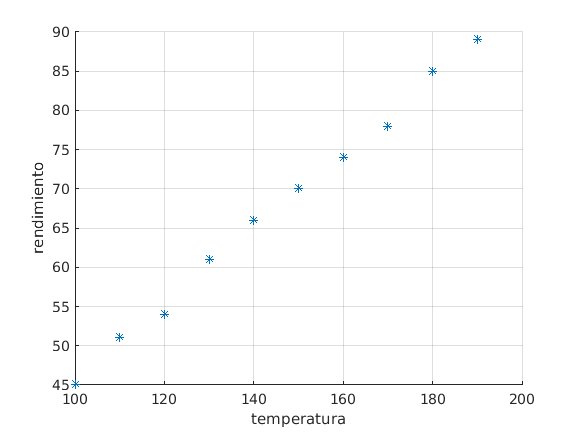

%diagrama de dispersion
scatter(x,y,'*')
grid on
xlabel('temperatura')
ylabel('rendimiento')

%matriz de covarianza y varianzas
v=cov(x,y)

v =   916.6667  442.7778
  442.7778  214.6778


covarianza=v(2,1)

covarianza = 442.7778

%coeficiente de correlacion
r=corrcoef(x,y)

r =     1.0000    0.9981
    0.9981    1.0000


coeficiente_correlacion=r(2,1)

coeficiente_correlacion = 0.9981

%regrecion lineal
%regresion lineal
n=length(x);
A=[n sum(x); sum(x) sum(x.^2)];
c=[sum(y); sum(x.*y)];
solucion=inv(A)*c;
bo=solucion(1);
b1=solucion(2);

syms xa
recta=bo+b1*xa

$$recta = \frac{797\,\mathrm{xa}}{1650}-\frac{6023990978845}{2199023255552}$$

xa=x;
scatter(x,y,'*')
grid on
hold on
plot(x,eval(recta))
xlabel('temperatura')
ylabel('rendimiento')
%coeficiente de determinacion
r2=sum((eval(recta)-mean(y)).^2)/sum((y-mean(y)).^2)

r2 = 0.9963

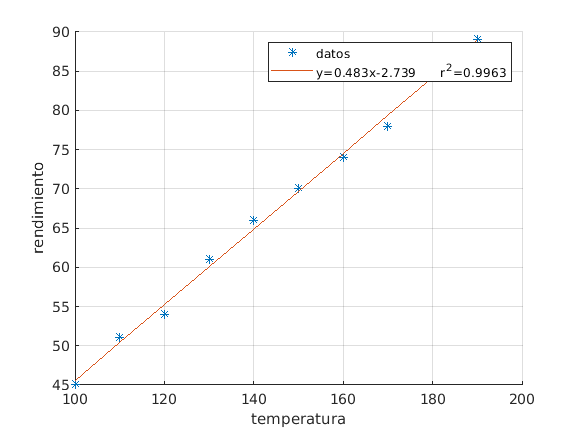


legend('datos','y=0.483x-2.739      r^2=0.9963')

%valor de 143°
valor_en_143=(0.483*143)-2.739

valor_en_143 = 66.3300